addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\in_progress_code
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\code_shared_groupNind
addpath C:\Users\nlab\Desktop\GitHub\ratrix\analysis\KC\individual_analysis_code

## LOADING MAPS VARS & BALL DATA

% load maps file for recording session (maps file generated by dfofMovie)
[df,frameT] = loadStage2MapsVars();

sizeDf =          188         231       46044


sizeFrameT =            1       46044


% load stimulus session data (comes from ballData folder on stimulus presentation computer)
[subjData,sessionFile,allStop,allResp,stimDetails,trialCond] = loadStage2subjSessVars();
% create figure title info
[date,subjName] = createTitleInfo(sessionFile,subjData);

date = 07 04 2021 

subjName = G6H305RT

exptDate = date;

## CROP FLUORESCENCE MOVIE

numFramesWholeSession = 46044

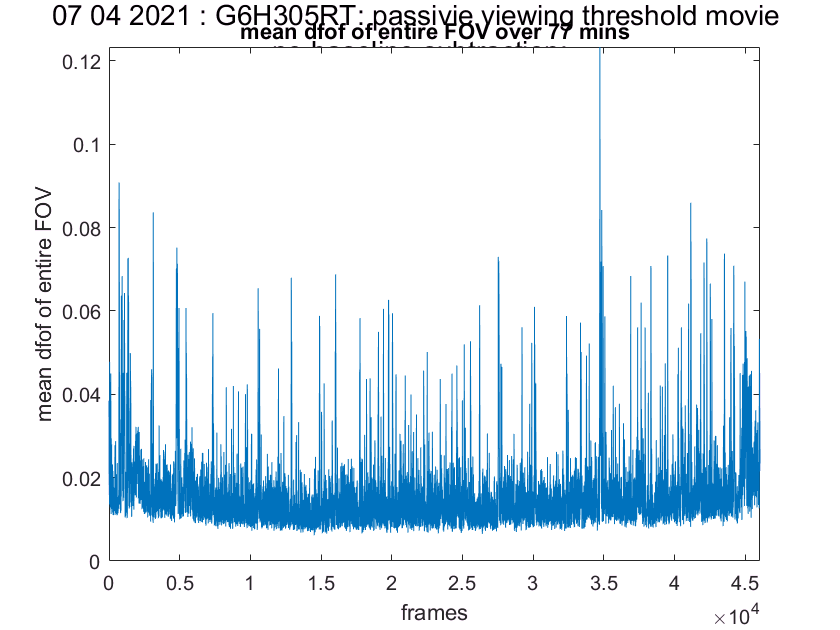

% check broad activity over whole field of view
meanDfEntireFOVvsFrames_wholeSessAnd1min(df,subjName,date);

range =          0    0.0500


colorMapOrNot = 1

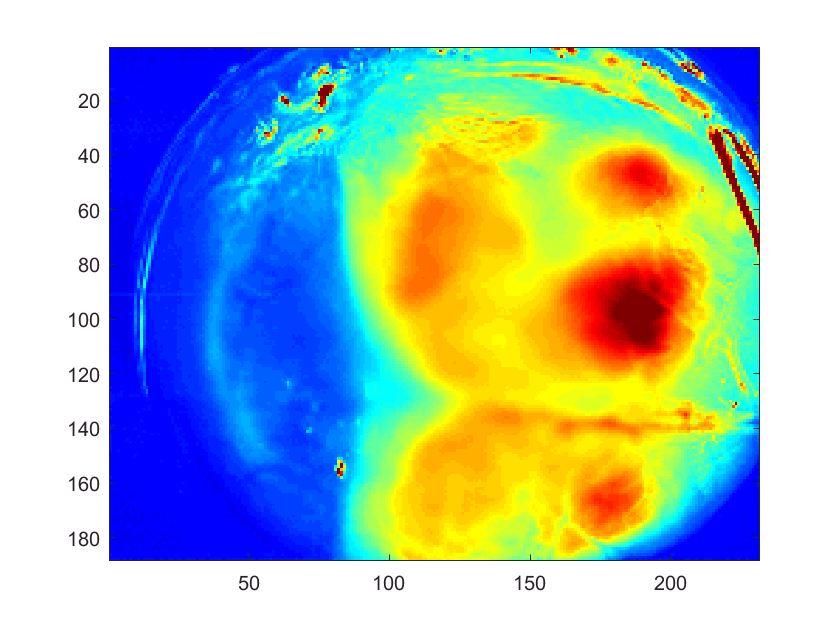

% pick the image/adjust the range on the image to be used for cropping in following step
[range,colorMapOrNot] = pickImageToCrop(df,subjName,date);

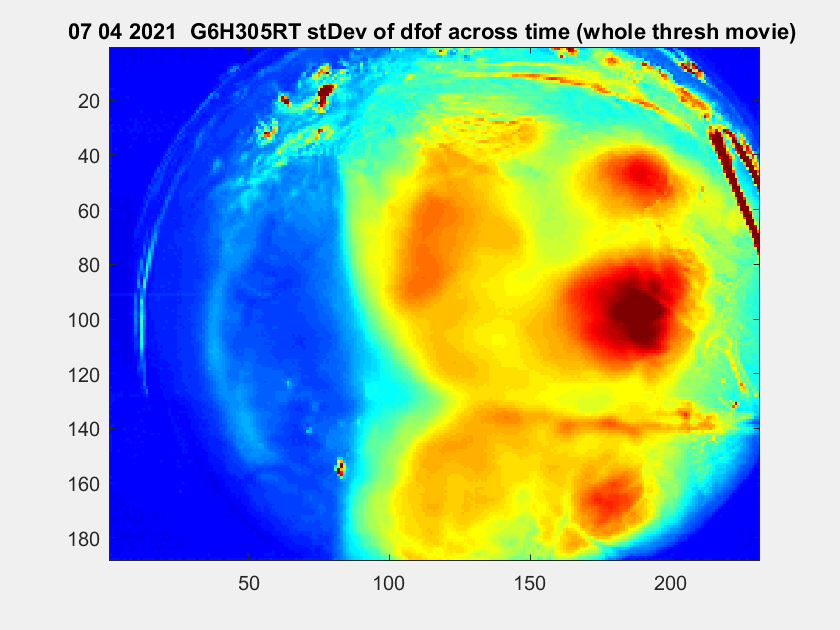

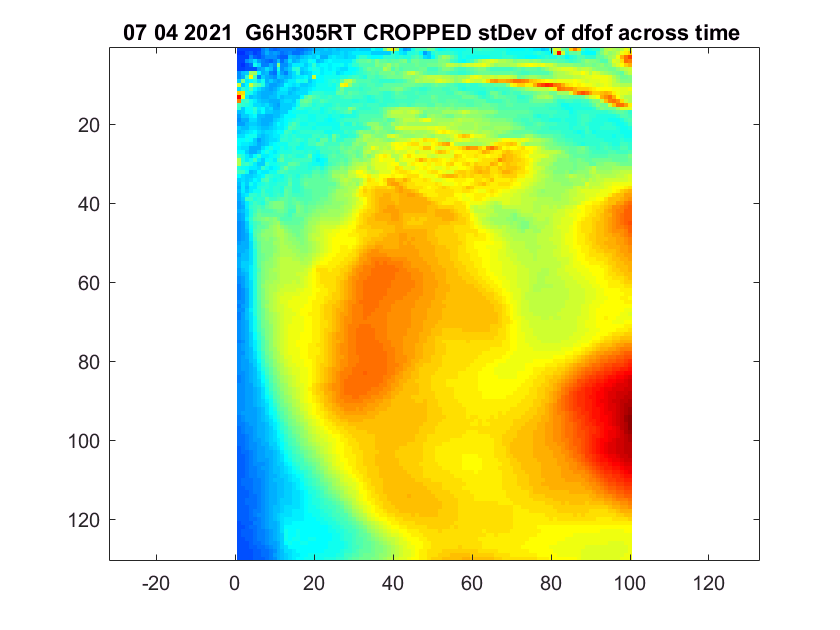

% crop image/movie & show cropped image
[xPtsCrop,yPtsCrop,dfCROP] = doCrop(df,range,colorMapOrNot,date,subjName);

## SEGMENT BY STIM ONSET

% get time of stimulus onsets for each trial
[stimOnsets] = onsetsStimFrames(allStop,allResp);

sizeOfOnsets =            1        1512



% how many early & late trials to filter out? change this in this meta script if need
earliestTrial = 6

earliestTrial = 6

numLateTrialsSubtract = 5

numLateTrialsSubtract = 5


% filter first and last few trials... can change num trials in code
[idxOnsetsMeetsCriteria,filteredStimOnsets] = filterOnsets_removeEarlyAndLateTrials(stimOnsets,earliestTrial,numLateTrialsSubtract);

sizeOnsetsMeetCriteria =            1        1502



% for each trial, get the indicies for the 1st imaging frame that folows the stimulus onset
[onsetImFrames] = onsetImagingFrames(filteredStimOnsets,frameT);

sizeOfOnsetImFrames =            1        1502



% picking pre & post imaging frames for indexing dfCROP into "chunks"

numPreStimFrames = 3

numPreStimFrames = 3

numPostStimFrames = 14

numPostStimFrames = 14


% make onsetDf variable
% use the indicies for the 1st imaging frame follwing stimulus onset, 
% plus the num pre & post frames defined earlier in this script,
% to index into dF % take 'chunks' of video around each stim onset
[onsetDf] = makeOnsetDf(onsetImFrames,dfCROP,numPreStimFrames,numPostStimFrames);

sizeOfOnsetDf =          130         100          18        1502


## GET STIM PARAMS for LOOPS and LEGENDS

% make vector of stim conditions in order of presentation/trial,
% & list of unique stim params (for looping)
[conOrderedByTrialMeetCriteria,uniqueContrasts,durOrderedByTrialMeetCriteria,uniqueDurations,conAndDurOrderedByTrialMeetCriteria] = getStimParamsNtrialConds(stimDetails,trialCond,idxOnsetsMeetsCriteria);

% in preparation for making pixel wise figures of flurescene at different stim conditions,
% make figure legends
[reigons,cons4Legend,cons4axes,durs4Legend,durs4Axes] = getSubtitleLegendNaxesInfo(uniqueContrasts,uniqueDurations);
reigons

reigons =     'V1'    'LP-HVA'    'LA-HVA'    'MA-HVA'    'control'


cons4Legend

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


durs4Legend

durs4Legend =     '1'    '2'    '4'    '8'    '16'


## PICK BASELINE & PEAK FRAMES

baselineIdx =      1     2     3


stimOnsetFrame = 4

stimOnsetFrame = 4

baselineIdx =      1     2     3


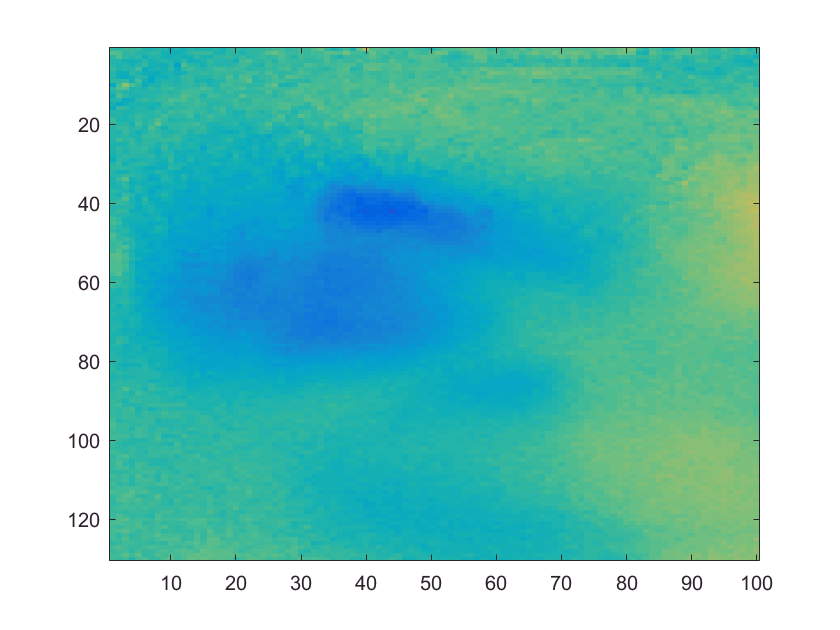

% pick the baseline indicies, show the mean baseline image, subtract from pix wise onsetDf
% images to demonstrate that these baseline indicies are appropriate. Diagnostic figures. 
% go in fcn and change 'baselineIdx' if want diff baseline range
[stimOnsetFrame,baselineIdx] = pickBaselineIdx(numPreStimFrames,conOrderedByTrialMeetCriteria,uniqueContrasts,date,subjName,onsetDf) 


% define peak activity frames (can change num frames in code, default is 10 frames post-stim onset frame)
numPeakFrames = 3;
[peakFrameIdx] = pickPeakFrames(stimOnsetFrame+1,numPeakFrames)

stimOnsetFrame = 5

peakFrameIdx =      6     7     8


## POINTS FOR ANALYSIS

range =          0    0.1100


colorMapOrNot = 1

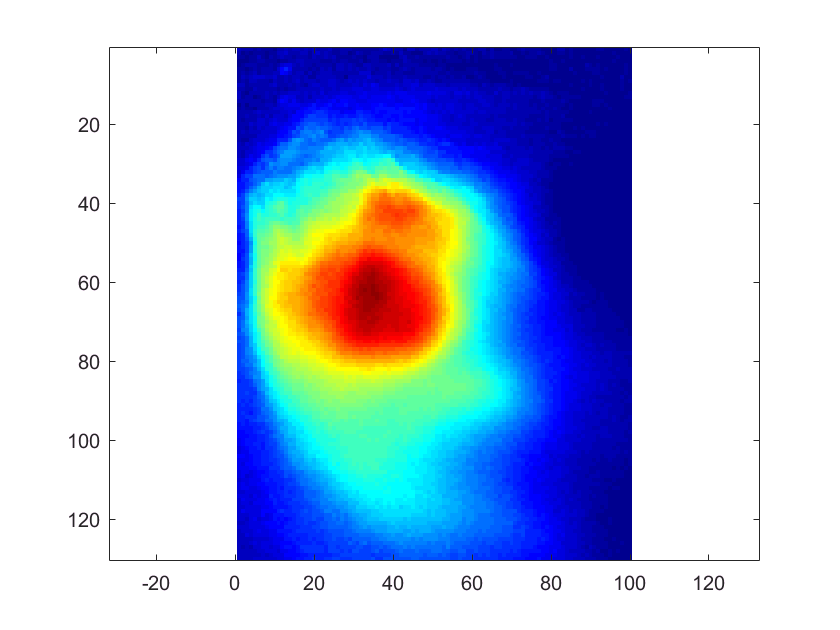

% Pick image to be used to pick points in visual areas in next step
[baselinedActIm,range,colorMapOrNot] = pickPeakActIm4Points(conAndDurOrderedByTrialMeetCriteria,uniqueContrasts,uniqueDurations,peakFrameIdx,onsetDf,baselineIdx);

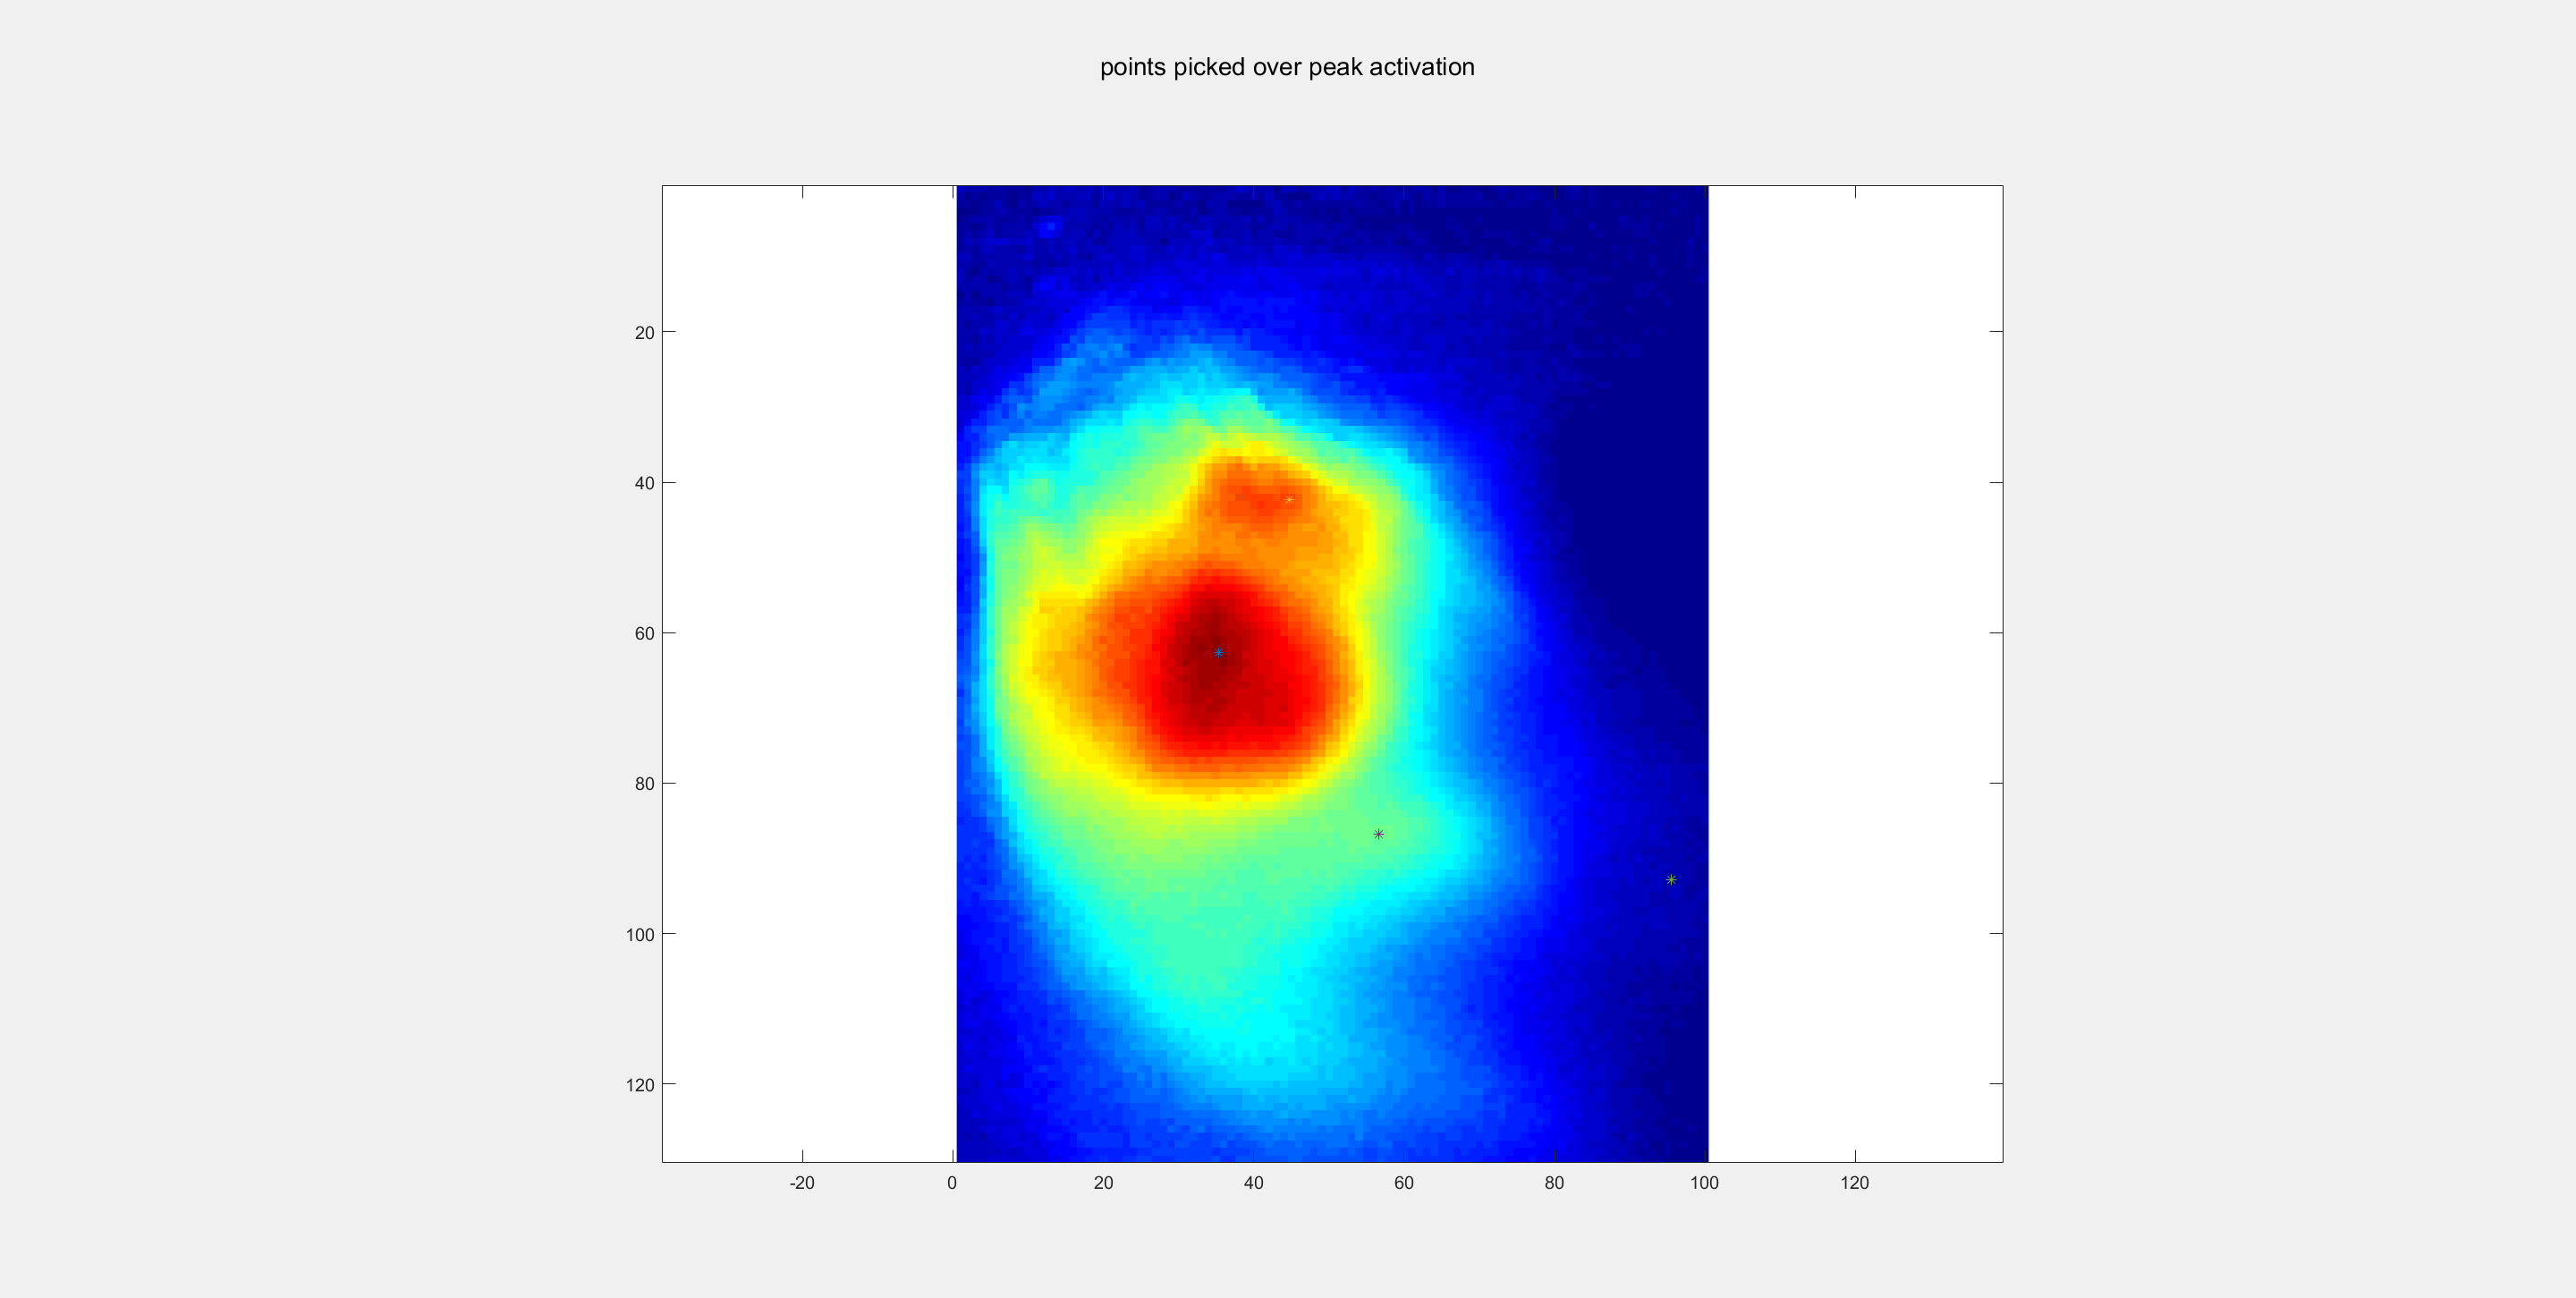

% actually pick the points
[xPickedPts,yPickedPts] = pickVisAreaPts(baselinedActIm,range,colorMapOrNot);


% make PTSdfof - this time I took the *mean over 25 pix squared (5x5 pix area)* for each point
[RoundXpts,RoundYpts,PTSdfof] = makePTSdfof(xPickedPts,yPickedPts,onsetDf,range,colorMapOrNot);

sizePTSdfof =            5          18        1502


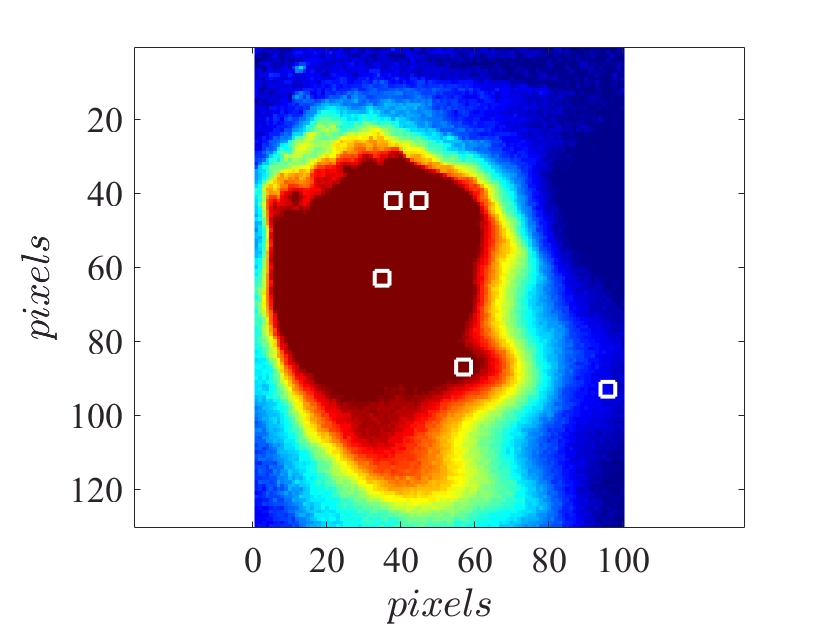

% Plot boxes over points picked
range = [0 0.05];
colorMapOrNot = 1;
visArea = 1:length(RoundXpts);

figure
imagesc(baselinedActIm,range)
if colorMapOrNot == 1
    colormap jet
end 
axis equal
hold on
    
% note: 1st point - each pt is one pixel 
%[RoundXpts(1,1),RoundYpts(1,1)]
% horizontal line, plus or minus 5 verical pixels

devitation = 2;

for i = visArea

    x = [RoundXpts(1,i)-devitation:1:RoundXpts(1,i)+devitation];
    y1 = [(RoundYpts(1,i)+devitation)*ones(1,length(x))];
    y2 = [(RoundYpts(1,i)-devitation)*ones(1,length(x))];
    
    % reverse x & y...
    plot(y1,x,'w','lineWidth',2)
    hold on
    plot(y2,x,'w','lineWidth',2)
    hold on
    
    x1 = [(RoundXpts(1,i)+devitation)*ones(1,length(x))];
    x2 = [(RoundXpts(1,i)-devitation)*ones(1,length(x))];
    y = [RoundYpts(1,i)-devitation:1:RoundYpts(1,i)+devitation];
    
    % reverse x & y...
    plot(y,x1,'w','lineWidth',2)
    hold on 
    plot(y,x2,'w','lineWidth',2)
    
    hold on 
    
end % end i loop

hold on 

set(gca, 'FontSize', 18, 'FontName', 'Times')
xlabel('$pixels$', 'Interpreter', 'latex')
ylabel('$pixels$', 'Interpreter', 'latex')

%clear xt
%xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
set(gca,'xtick',0:20:100); 
set(gca,'ytick',20:20:120); 

%set(gca,'xticklabel',xt);


% save plot
%print('points_picked.png','-dpng')


 % Make 3 IMAGE to help idenitfy visual areas & blood vessels...
% first run do_topo, which ***needs the recording session to be un-commented 
% in batch file*** 
formatSpec = '%s%s%s';
dateNoSpaces = sprintf(formatSpec,date(1:2),date(4:5),date(9:10));
[meanpolar,ypts,xpts] = do_topo(subjName,dateNoSpaces);

% now SHOW the 3 figs (despite what that the name of the function says)
% CHANGE the tif file/folder path in ehere each time
visArea = 1:length(RoundYpts);
global visArea

global RoundXpts

global RoundYpts

[tifPic] = pickVisAreaPts3figs_051022test(meanpolar,ypts,xpts,baselinedActIm,df,range);

Undefined function or variable 'meanpolar'.


## GET NON-SEGMENTED V1 DF TRACE FOR ENTIRE RECORDING

## (for pupil analysis)

% note that there is no way to baseline a trace for the entire recording...

clear dfofV1Point
dfofV1Point(1,:,:) = dfCROP(RoundXpts(1),RoundYpts(1),:,:);

sizeDfofV1Point = size(dfofV1Point)

sizeDfofV1Point =            1       46044


## RUNNING ANALYSIS

sizeOf_allXYcursorCoordinatesStopAndRespFramesAlltrials =            2      272403


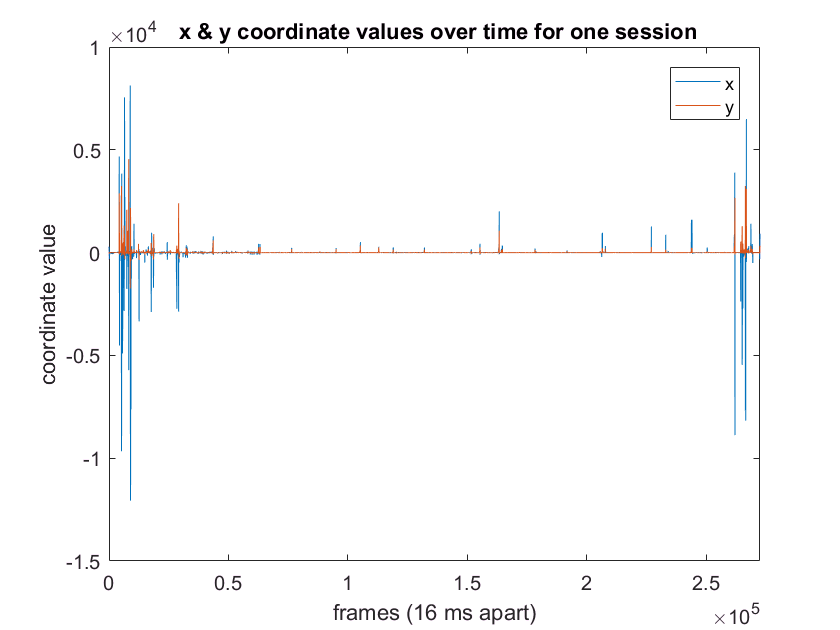

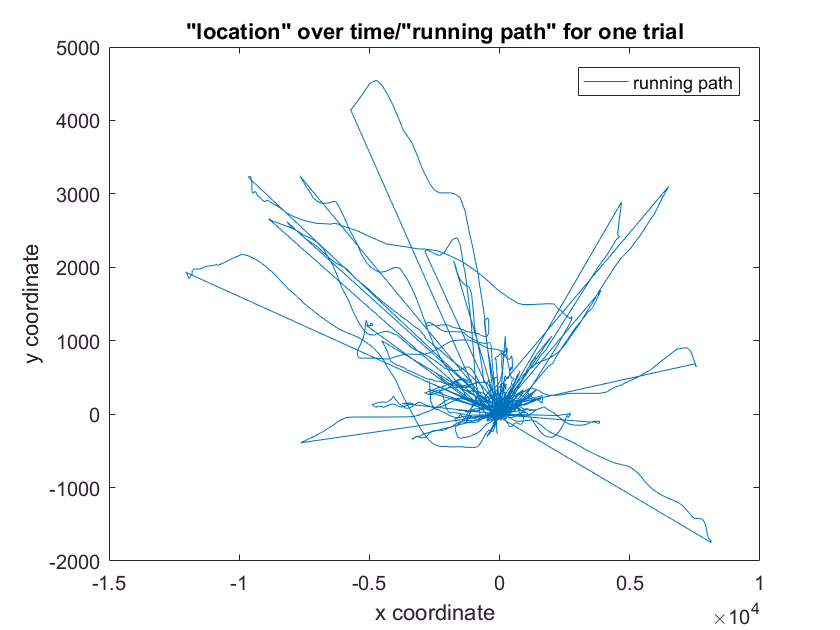

% x & y coordinates, run path
[allXYcursorCoordinatesStopAndRespFramesAlltrials] = stitchBackCursorCoordinatesForAllTrialsAndFrames(allStop,allResp);


% calculate mean run speed for each trial
[meanSpeedAllTrials] = calcMeanRunSpeedAllTrials(allStop,allResp);

numTrialsInSession = 1512

sizeOf_meanSpeedAllTrials =            1        1512



%FILTER first and last few trials... can change num trials in code
[runIdxOnsetsMeetsCriteria,meanSpeedAllTrials] = filterOnsets_removeEarlyAndLateTrials(meanSpeedAllTrials,earliestTrial,numLateTrialsSubtract);

sizeOnsetsMeetCriteria =            1        1502


sizemeanSpeedAllTrials = size(meanSpeedAllTrials)

sizemeanSpeedAllTrials =            1        1502


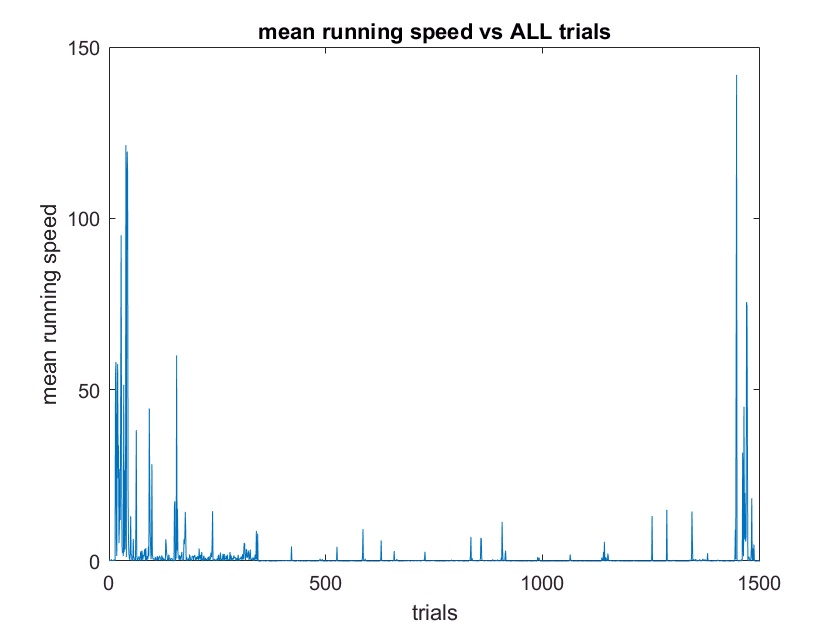


% Plot

figure
plot(meanSpeedAllTrials)
xlabel('trials')
ylabel('mean running speed')
title('mean running speed vs ALL trials')
xlim([0 length(meanSpeedAllTrials)])

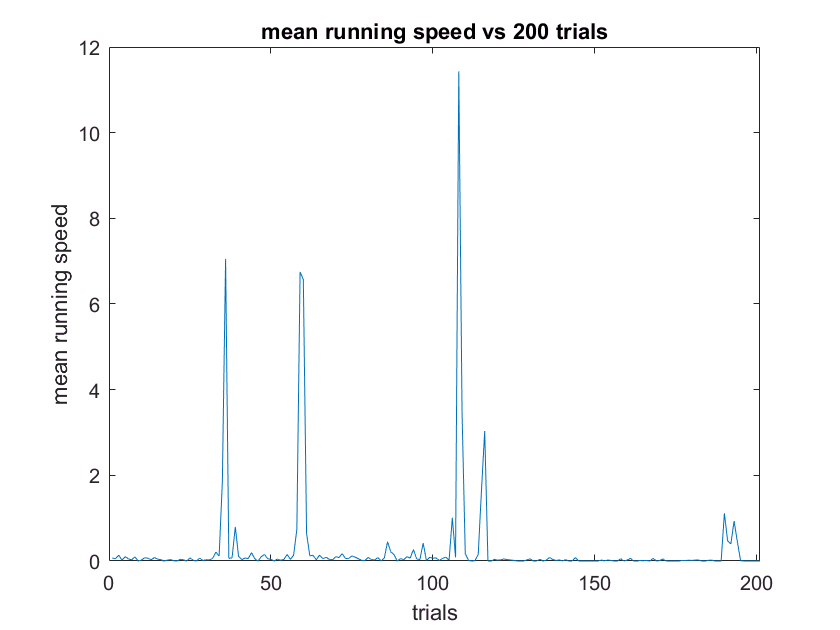

%ylim([-5 500])
% smaller range of trials
figure
xRangeMin = 800;
xRangeMax = 1000;
plot(meanSpeedAllTrials(1,xRangeMin:xRangeMax))
xlabel('trials')
ylabel('mean running speed')
title('mean running speed vs 200 trials')
xlim([0 length(meanSpeedAllTrials(1,xRangeMin:xRangeMax))])

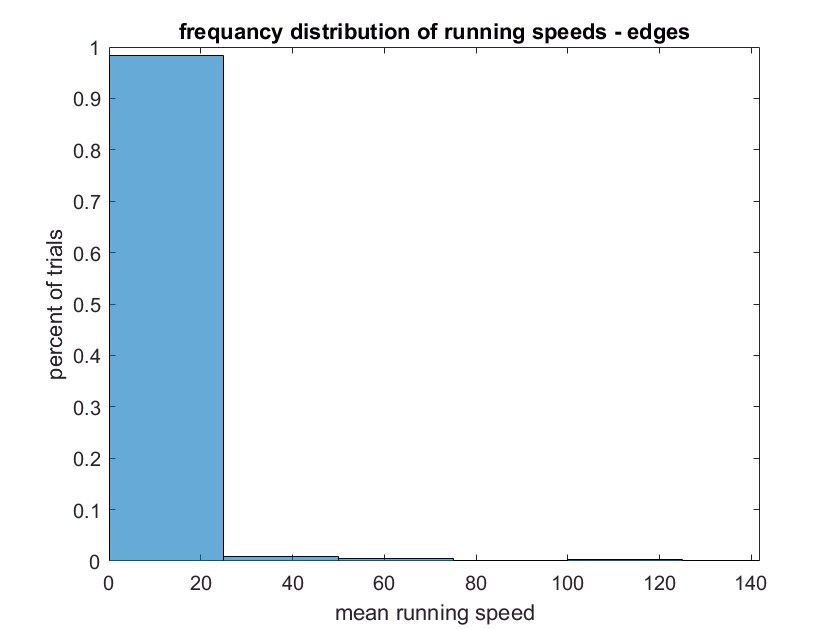

%ylim([-5 500])

% histos

%histogram(meanSpeedAllTrials);
%numBins = 10;
%histogram(meanSpeedAllTrials,numBins)
%histogram(meanSpeedAllTrials,numBins,'normalization','probability')
%histogram(meanSpeedAllTrials,'binWidth',20,'normalization','probability')

%Bin edges, specified as a vector. edges(1) is the left edge of the first bin, 
%and edges(end) is the right edge of the last bin.

edges = [0 0:25:max(meanSpeedAllTrials) max(meanSpeedAllTrials)];
%h = histogram(meanSpeedAllTrials,edges);
histogram(meanSpeedAllTrials,edges,'normalization','probability');
xlim([0 max(meanSpeedAllTrials)])
ylabel('percent of trials')
xlabel('mean running speed')
title('frequancy distribution of running speeds - edges')


%Each bin includes the left edge, but does not include the right edge, 
%except for the last bin which includes both edges
%numedges = ;
%histogram(X,numedges)

% x = randn(1000,1);
% edges = [-2 -2:0.25:2 2];
% h = histogram(x,edges);

%numTrials = length(meanSpeedAllTrials)
% numBins = 10
% 
% histogram(meanSpeedAllTrials,numBins,'normalization','probability')
% ylabel('fraction of trials')
% xlabel('mean running speed')
% title('frequancy distribution of running speeds - bins')
% xlim([0 round(max(meanSpeedAllTrials)+10)])
% set(gca,'xtick',0:25:round(max(meanSpeedAllTrials)+10));
% ylim([0 1])


## PUPIL ANALYSIS

% LOAD DLC/python PUPIL TRACKING data
[f p] = uigetfile('*.mat','REYE pupil track file');
load(fullfile(p,f));

sizeLongAxis = length(longaxis)


% plot pupil diamter over time (in pix)
figure
plot(longaxis)
ylabel('diameter(pix)')
xlabel('frames (60 Hz)')
xlim([0 sizeLongAxis])
title('pupil diameter over time')

sizeLongAxis = length(longaxis)
%sizeDf = size(df,3)

% ONSET SEGMENTING - 
% line up pupil dimater trace with V1 dfof trace for each
% stim onset chunk

% Index long axis with the values in onsetImFrames, 
% which are the indicies of imaging frames at the onset of a trial

% long axis is downsampled to 10Hz so time stamps are not needed,
% only imagaing frame indicies

% NOTE: onsetImFrames is already fitered away early & late trials so don't filter pupil diamters again

clear o
for o = 1:length(onsetImFrames)
    
    % select only the pupil frames right before & after the onset imaging frame of each stim
    eachOnsetPupil = longaxis(1,onsetImFrames(o)-numPreStimFrames:onsetImFrames(o)+numPostStimFrames);
    
    allOnsetPupils(o,:) = eachOnsetPupil;

end

%sizeOfEachOnsetPupil = size(eachOnsetPupil)
sizeOfAllOnsetPupils = size(allOnsetPupils)

% plot one trial
figure
plot(allOnsetPupils(400,:))

% get mean pupil diamter for each trial

clear p 

for p = 1:length(allOnsetPupils)
    
    meanPupilDiameterEachTrial = nanmean(allOnsetPupils(p,:));
    meanPupilDiameterAllTrials(1,p) = meanPupilDiameterEachTrial;
    
end
sizeMeanPupilDiameterAllTrials = size(meanPupilDiameterAllTrials)

% Q: if I'm plotting group pupil histos next, I don't really want normalized yet do I?
% But different mice also have different sized pupils (no?) diff lighting conditions (no)?...
% noramlize pupil diamter to miniumum pupil diameter
meanPupilDiameterAllTrials = meanPupilDiameterAllTrials-min(meanPupilDiameterAllTrials);

% (DONT DO FOR PUPILS) FILTER first and last few trials... can change num trials in code
%[pupIdxOnsetsMeetsCriteria,meanPupilDiameterAllTrials] = filterOnsets_removeEarlyAndLateTrials(meanPupilDiameterAllTrials,earliestTrial,numLateTrialsSubtract);
%sizeMeanPupilDiameterAllTrials = size(meanPupilDiameterAllTrials)

% histo of pupil diameter sizes
edges = [0 0:1:max(meanPupilDiameterAllTrials) max(meanPupilDiameterAllTrials)];
histogram(meanPupilDiameterAllTrials,edges,'Normalization','probability')
xlim([0 max(meanPupilDiameterAllTrials)])
title('frequency of pupil diameters')
xlabel('pupil diamater (a.u.)')
ylabel('percent of trials')

## RUN & PUPIL TOGETHER

% % pick a threshold... what percentage of trials above & below it?
% % based on histogram, I picked 60 pix/frame threshold for running
% runThresh = 60
% numTrials = length(meanSpeedAllTrials)
% numTrialsOverThresh = sum(meanSpeedAllTrials>=runThresh)
% percentTrialsOverThresh = (numTrialsOverThresh/numTrials)*100
% % the meanSpeedAllTrials vector has 1 row, each column has
% % the mean speed for that trial (*not* onset chunk)
% % note that resolution for cursor is 6 times higher than for 
% % imaging, so the extra frames (all trials-onset chunk) don't
% % count for as much (divide by 6)
% % indicies for trials that meet our threshold
% idxRunTrials = find(meanSpeedAllTrials>=runThresh);
% numRunTrials = length(idxRunTrials);
% % indicies for stationary trials
% idxStatTrials = find(meanSpeedAllTrials<=runThresh);
% numStatTrials = length(idxStatTrials)
% 
% % DEFINE THRESHOLD
% pupThreshold = 15
% % DEFINE LARGE VS SMALL VS MED ETC PUPIL TRIALS
% % indicies for trials that meet our threshold
% % USE to INDEX trials in PTSdfof onset CHUNKS
% idxLargePupilTrials = find(meanPupilDiameterAllTrials>=pupThreshold);
% idxSmallPupilTrials = find(meanPupilDiameterAllTrials<=pupThreshold);
% numTrials = length(meanPupilDiameterAllTrials)
% numTrialsOverThresh = length(idxLargePupilTrials)
% numTrialsUnderThresh = length(idxSmallPupilTrials)
% percentTrialsOverThresh = (numTrialsOverThresh/numTrials)*100


% plot run vs pup   
x_axis = 1:length(meanSpeedAllTrials);
figure
formatSpec = '%s %s \n'; % \n
titleText = sprintf(formatSpec,subjName,date);
suptitle(titleText)
subplot(2,1,1)
plot(x_axis,meanSpeedAllTrials,'r')
%bar(x_axis,meanSpeedAllTrials,'r')
%scatter(x_axis,meanSpeedAllTrials,'r')
xlim([0 length(x_axis)])
ylabel('magnitude (a.u.)')
xlabel('trials')
hold on
% % run thresh line
% clear y
% y(1,1:length(meanSpeedAllTrials)) = runThresh;
% plot(1:length(y),y,'b')
title('run speed')
xlim([0 length(meanSpeedAllTrials)])
%pupil 
x_axis = 1:length(meanPupilDiameterAllTrials);
subplot(2,1,2)
%bar(x_axis,meanPupilDiameterAllTrials,'b')
plot(x_axis,meanPupilDiameterAllTrials,'k')
%scatter(x_axis,meanPupilDiameterAllTrials,'k')
hold on 
% pup thresh line
% clear y
% y(1,1:length(meanPupilDiameterAllTrials)) = pupThreshold;
% plot(1:length(y),y,'g')
title('pupil diameter')
xlim([0 length(meanPupilDiameterAllTrials)])
xlabel('trials')
ylabel('magnitude (a.u.)')


% % % DIFF
% % 
% % % plot run vs pup   
% % x_axis = 1:length(meanSpeedAllTrials)-1;
% % figure
% % titleText = sprintf('diff\n')
% % suptitle(titleText)
% % subplot(2,1,1)
% % plot(x_axis,diff(meanSpeedAllTrials),'r')
% % %scatter(x_axis,diff(meanSpeedAllTrials),'r')
% % title('run speed')
% % xlim([0 length(x_axis)])
% % ylabel('magnitude (a.u.)')
% % xlabel('trials')
% % hold on
% % 
% % %pupil 
% % x_axis = 1:length(meanPupilDiameterAllTrials)-1;
% % subplot(2,1,2)
% % plot(x_axis,diff(meanPupilDiameterAllTrials),'k')
% % %scatter(x_axis,diff(meanPupilDiameterAllTrials),'k')
% % hold on 
% % title('pupil diameter')
% % xlim([0 length(meanPupilDiameterAllTrials)-1])
% % xlabel('trials')
% % ylabel('magnitude (a.u.)')


% % downsample, showing boder trend over whole session
% % run speed
% clear downSampledMnSpeadAllTrials
% clear dwnSampIdx
% sampsPerMn = 5;
% dwnSampIdx = [1:1:sampsPerMn];
% for samp = 1:round(length(meanSpeedAllTrials)/sampsPerMn)-sampsPerMn % i want a new vector w/number of downsampled points
%     downSampledMnSpeedAllTrials(1,samp) = mean(meanSpeedAllTrials(1,dwnSampIdx));
%     dwnSampIdx = dwnSampIdx+sampsPerMn;
% end 
% 
% %pupil dimater
% % run speed
% clear downSampledMnPupDiameterAllTrials
% clear dwnSampIdx
% dwnSampIdx = [1:1:sampsPerMn];
% for samp = 1:round(length(meanPupilDiameterAllTrials)/sampsPerMn)-sampsPerMn % i want a new vector w/number of downsampled points
%     downSampledMnPupDiameterAllTrials(1,samp) = mean(meanPupilDiameterAllTrials(1,dwnSampIdx));
%     dwnSampIdx = dwnSampIdx+sampsPerMn;
% end 
% 
% 
% %  downsample,  whole session
% x_axis = 1:length(downSampledMnSpeedAllTrials);
% figure
% titleText = sprintf('dwn samp\n')
% suptitle(titleText)
% subplot(2,1,1)
% %plot(x_axis,downSampledMnSpeedAllTrials,'r')
% scatter(x_axis,downSampledMnSpeedAllTrials,'r')
% xlim([0 length(x_axis)])
% ylabel('magnitude (a.u.)')
% xlabel('trials')
% hold on
% % run thresh line
% clear y
% y(1,1:length(downSampledMnSpeedAllTrials)) = runThresh;
% plot(1:length(y),y,'b')
% title('run speed')
% xlim([0 length(downSampledMnSpeedAllTrials)])
% %pupil 
% x_axis = 1:length(downSampledMnPupDiameterAllTrials);
% subplot(2,1,2)
% %plot(x_axis,downSampledMnPupDiameterAllTrials,'k')
% scatter(x_axis, downSampledMnPupDiameterAllTrials,'k')
% hold on 
% % pup thresh line
% clear y
% y(1,1:length(downSampledMnPupDiameterAllTrials)) = pupThreshold;
% plot(1:length(y),y,'g')
% title('pupil diameter')
% xlim([0 length(downSampledMnPupDiameterAllTrials)])
% xlabel('trials')
% ylabel('magnitude (a.u.)')


% % plot diff downsample (whole trial)
% x_axis = 1:length(downSampledMnSpeedAllTrials)-1;
% figure
% titleText = sprintf('dwnSamp & diff\n')
% suptitle(titleText)
% subplot(2,1,1)
% plot(x_axis,diff(downSampledMnSpeedAllTrials),'r')
% %scatter(x_axis,diff(downSampledMnSpeedAllTrials),'r')
% xlim([0 length(x_axis)])
% ylabel('magnitude (a.u.)')
% xlabel('trials')
% hold on
% title('run speed')
% xlim([0 length(downSampledMnSpeedAllTrials)-1])
% %pupil 
% x_axis = 1:length(downSampledMnPupDiameterAllTrials)-1;
% subplot(2,1,2)
% plot(x_axis,diff(downSampledMnPupDiameterAllTrials),'k')
% %scatter(x_axis,diff(downSampledMnPupDiameterAllTrials),'k')
% hold on 
% title('pupil diameter')
% xlim([0 length(downSampledMnPupDiameterAllTrials-1)])
% xlabel('trials')
% ylabel('magnitude (a.u.)')


% % smaler time range (not downsampled)
% 
% % length of downsampled trace
% numTrials = length(meanSpeedAllTrials);
% 
% % for first down samp point, what percent into start of trace?:
% howFarIn = (1/3); % 20% in = 1/55, 80% in = 4/5, etc
% startTrial = round(numTrials*howFarIn);
% 
% % for last down samp point, what percent away from end of trace?
% howFarTilEnd = (1/3);
% endTrial = numTrials-round(numTrials*howFarTilEnd);
% 
% % run speed
% x_axis = 1:length(meanSpeedAllTrials(1,startTrial:endTrial));
% figure
% titleText = sprintf('less trials\n')
% suptitle(titleText)
% subplot(2,1,1)
% %bar(x_axis,meanSpeedAllTrials(1,startTrial:endTrial),'r')
% plot(x_axis,meanSpeedAllTrials(1,startTrial:endTrial),'r')
% %scatter(x_axis,meanSpeedAllTrials(1,startTrial:endTrial),'r')
% xlim([0 length(x_axis)])
% ylabel('magnitude (a.u.)')
% xlabel('trials')
% hold on
% % run thresh line
% clear y
% y(1,1:length(meanSpeedAllTrials(1,startTrial:endTrial))) = runThresh;
% plot(1:length(y),y,'b')
% title('run speed')
% xlim([0 length(meanSpeedAllTrials(1,startTrial:endTrial))])
% %pupil 
% x_axis = 1:length(meanPupilDiameterAllTrials(1,startTrial:endTrial));
% subplot(2,1,2)
% %bar(x_axis,meanPupilDiameterAllTrials(1,startTrial:endTrial),'b')
% plot(x_axis,meanPupilDiameterAllTrials(1,startTrial:endTrial),'k')
% %scatter(x_axis,meanPupilDiameterAllTrials(1,startTrial:endTrial),'k')
% hold on 
% % pup thresh line
% clear y
% y(1,1:length(meanPupilDiameterAllTrials(1,startTrial:endTrial))) = pupThreshold;
% plot(1:length(y),y,'g')
% title('pupil diameter')
% xlim([0 length(meanPupilDiameterAllTrials(1,startTrial:endTrial))])
% xlabel('trials')
% ylabel('magnitude (a.u.)')


% % diff, smaller time range
% 
% yMax = 10;
% yMin = -10;
% yLimit = [yMin yMax];
% % run speed
% x_axis = 1:length(meanSpeedAllTrials(1,startTrial:endTrial-1));
% figure
% titleText = sprintf('diff, less trials\n')
% suptitle(titleText)
% subplot(2,1,1)
% plot(x_axis,diff(meanSpeedAllTrials(1,startTrial:endTrial)),'r')
% %scatter(x_axis,meanSpeedAllTrials(1,startTrial:endTrial),'r')
% xlim([0 length(x_axis)])
% ylabel('magnitude (a.u.)')
% xlabel('trials')
% title('run speed')
% xlim([0 length(meanSpeedAllTrials(1,startTrial:endTrial))])
% hold on
% %pupil 
% x_axis = 1:length(meanPupilDiameterAllTrials(1,startTrial:endTrial-1));
% subplot(2,1,2)
% plot(x_axis,diff(meanPupilDiameterAllTrials(1,startTrial:endTrial)),'k')
% %scatter(x_axis,meanPupilDiameterAllTrials(1,startTrial:endTrial),'k')
% title('pupil diameter')
% xlim([0 length(meanPupilDiameterAllTrials(1,startTrial:endTrial))])
% xlabel('trials')
% ylabel('magnitude (a.u.)')
% ylim(yLimit)


% % downsampled, smaller time range 
% 
% % length of downsampled trace
% numDwnSampPts = length(downSampledMnSpeedAllTrials);
% 
% % for first down samp point, what percent into start of trace?:
% %howFarIn = (1/3); % 20% in = 1/55, 80% in = 4/5, etc
% startPt = round(numDwnSampPts*howFarIn);
% 
% % for last down samp point, what percent away from end of trace?
% %howFarTilEnd = (1/3)
% endPt = numDwnSampPts-round(numDwnSampPts*howFarTilEnd)
% 
% % run speed
% x_axis = 1:length(downSampledMnSpeedAllTrials(1,startPt:endPt));
% figure
% titleText = sprintf('dwnSamp, less trials\n')
% suptitle(titleText)
% subplot(2,1,1)
% plot(x_axis,downSampledMnSpeedAllTrials(1,startPt:endPt),'r')
% %scatter(x_axis,meanSpeedAllTrials(1,startTrial:endTrial),'r')
% xlim([0 length(x_axis)])
% ylabel('magnitude (a.u.)')
% xlabel('trials')
% hold on
% % run thresh line
% clear y
% y(1,1:length(downSampledMnSpeedAllTrials(1,startPt:endPt))) = runThresh;
% plot(1:length(y),y,'b')
% title('run speed')
% xlim([0 length(downSampledMnSpeedAllTrials(1,startPt:endPt))])
% %pupil 
% x_axis = 1:length(downSampledMnPupDiameterAllTrials(1,startPt:endPt));
% subplot(2,1,2)
% plot(x_axis,downSampledMnPupDiameterAllTrials(1,startPt:endPt),'k')
% %scatter(x_axis,meanPupilDiameterAllTrials(1,startTrial:endTrial),'k')
% hold on 
% % pup thresh line
% clear y
% y(1,1:length(downSampledMnPupDiameterAllTrials(1,startPt:endPt))) = pupThreshold;
% plot(1:length(y),y,'g')
% title('pupil diameter')
% xlim([0 length(downSampledMnPupDiameterAllTrials(1,startPt:endPt))])
% xlabel('trials')
% ylabel('magnitude (a.u.)')


% % diff, dwn samp, less trials 
% % run speed
% x_axis = 1:length(downSampledMnSpeedAllTrials(1,startPt:endPt))-1;
% figure
% titleText = sprintf('diff dwnSamp, less trials\n')
% suptitle(titleText)
% subplot(2,1,1)
% plot(x_axis,diff(downSampledMnSpeedAllTrials(1,startPt:endPt)),'r')
% %scatter(x_axis,diff(meanSpeedAllTrials(1,startTrial:endTrial)),'r')
% xlim([0 length(x_axis)])
% ylabel('magnitude (a.u.)')
% xlabel('trials')
% title('run speed')
% xlim([0 length(downSampledMnSpeedAllTrials(1,startPt:endPt))-1])
% 
% hold on
% 
% %pupil 
% x_axis = 1:length(downSampledMnPupDiameterAllTrials(1,startPt:endPt))-1;
% subplot(2,1,2)
% plot(x_axis,diff(downSampledMnPupDiameterAllTrials(1,startPt:endPt)),'k')
% %scatter(x_axis,meanPupilDiameterAllTrials(1,startTrial:endTrial),'k')
% title('pupil diameter')
% xlim([0 length(downSampledMnPupDiameterAllTrials(1,startPt:endPt))-1])
% xlabel('trials')
% ylabel('magnitude (a.u.)')


% SCATTER RUN VS PUP
figure
scatter(meanSpeedAllTrials,meanPupilDiameterAllTrials)
xlabel('run speed (a.u.)')
ylabel('pupil diameter (a.u.)')
hold on 
% % plot pup thresh line
% lengthPupThreshOnX = max(meanSpeedAllTrials);
% clear pupThreshYval
% pupThreshYval(1,1:lengthPupThreshOnX) = pupThreshold;
% pupThreshXaxis = [1:lengthPupThreshOnX];
% plot(pupThreshXaxis,pupThreshYval,'g')
hold on
% % plot run thresh line
% lengthRunThreshOnY = max(meanPupilDiameterAllTrials);
% clear runThreshYval
% runThreshXval(1,1:lengthRunThreshOnY) = runThresh;
% runThreshYaxis = [1:lengthRunThreshOnY];
% plot(runThreshXval,runThreshYaxis,'b')
% hold on


% % SCATTER RUN VS PUP
% figure
% scatter(meanPupilDiameterAllTrials,meanSpeedAllTrials)
% ylabel('run speed (a.u.)')
% xlabel('pupil diameter (a.u.)')
% hold on 
% % plot pup thresh line
% lengthPupThreshOnX = max(meanSpeedAllTrials);
% clear pupThreshYval
% pupThreshYval(1,1:lengthPupThreshOnX) = pupThreshold;
% pupThreshXaxis = [1:lengthPupThreshOnX];
% plot(pupThreshYval,pupThreshXaxis,'g')
% hold on
% % plot run thresh line
% lengthRunThreshOnY = max(meanPupilDiameterAllTrials);
% clear runThreshYval
% runThreshXval(1,1:lengthRunThreshOnY) = runThresh;
% runThreshYaxis = [1:lengthRunThreshOnY];
% plot(runThreshYaxis,runThreshXval,'b')
% hold on


% % SCATTER DIFF RUN VS DIFF  PUP
% figure
% scatter(diff(meanSpeedAllTrials),diff(meanPupilDiameterAllTrials))
% xlabel('run speed (a.u.)')
% ylabel('pupil diameter (a.u.)')
% hold on 


% % [val,pos]=intersect(a,b)  % gives common val and its position in 'a'
% 
% loPupStat_idx = intersect(idxSmallPupilTrials,idxStatTrials);
% hiPupRun_idx = intersect(idxLargePupilTrials,idxRunTrials);
% 
% loPupRun_idx = intersect(idxSmallPupilTrials,idxRunTrials);
% hiPupStat_idx = intersect(idxLargePupilTrials,idxStatTrials);
% 
% figure
% scatter(meanSpeedAllTrials(loPupStat_idx),meanPupilDiameterAllTrials(loPupStat_idx),'b')
% hold on 
% scatter(meanSpeedAllTrials(hiPupRun_idx),meanPupilDiameterAllTrials(hiPupRun_idx),'r')
% hold on 
% scatter(meanSpeedAllTrials(loPupRun_idx),meanPupilDiameterAllTrials(loPupRun_idx),'g')
% hold on 
% scatter(meanSpeedAllTrials(hiPupStat_idx),meanPupilDiameterAllTrials(hiPupStat_idx),'m')
% 
% xlabel('run speed a.u.')
% ylabel('pup size a.u.')
% 
% percentTrials_loPupStat_idx = (length(loPupStat_idx)/length(meanSpeedAllTrials))*100 % percent of totoal trials
% percentTrials_hiPupRun_idx = (length(hiPupRun_idx)/length(meanSpeedAllTrials))*100
% 
% percentTrials_loPupRun_idx = (length(loPupRun_idx)/length(meanSpeedAllTrials))*100
% percentTrials_hiPupStat_idx = (length(hiPupStat_idx)/length(meanSpeedAllTrials))*100

% % ** NAVIGATE to correct folder **
 
% save('081321_G6H124RN_new_badEye_Vars4IndAndGroupAnalyses.mat',...
%     'stimDetails','subjData','trialCond','subjName','date','exptDate',...
%     'frameT','numPreStimFrames','numPostStimFrames','onsetImFrames','onsetDf',...
%     'idxOnsetsMeetsCriteria','peakFrameIdx','stimOnsetFrame','baselineIdx',...
%     'baselinedActIm','xPickedPts','yPickedPts','RoundXpts','RoundYpts',...
%     'PTSdfof','meanSpeedAllTrials','runIdxOnsetsMeetsCriteria',...
%     'dfofV1Point','longaxis','allOnsetPupils','meanPupilDiameterAllTrials','earliestTrial',...
%     'numLateTrialsSubtract','-v7.3') % '-append',

%save('122422_2DLT_newVars4IndAndGroupAnalyses.mat','exptDate','-append')
%save('122422_2DLT_newVars4IndAndGroupAnalyses.mat','meanPupilDiameterAllTrials','-append')


% save('122822_2GLT_newVars4IndAndGroupAnalyses.mat',...
%     'stimDetails','subjData','trialCond','subjName','date',...
%     'frameT','numPreStimFrames','numPostStimFrames','onsetImFrames','onsetDf',...
%     'idxOnsetsMeetsCriteria','peakFrameIdx','stimOnsetFrame','baselineIdx',...
%     'baselinedActIm','xPickedPts','yPickedPts','RoundXpts','RoundYpts',...
%     'PTSdfof','meanSpeedAllTrials','runThresh','idxRunTrials','idxStatTrials','runIdxOnsetsMeetsCriteria',...
%     'dfofV1Point','longaxis','allOnsetPupils','meanPupilDiameterAllTrials','pupThreshold',...
%     'idxSmallPupilTrials','idxLargePupilTrials','earliestTrial',...
%     'numLateTrialsSubtract','-v7.3') % '-append',

fntSize = 12

fntSize = 12

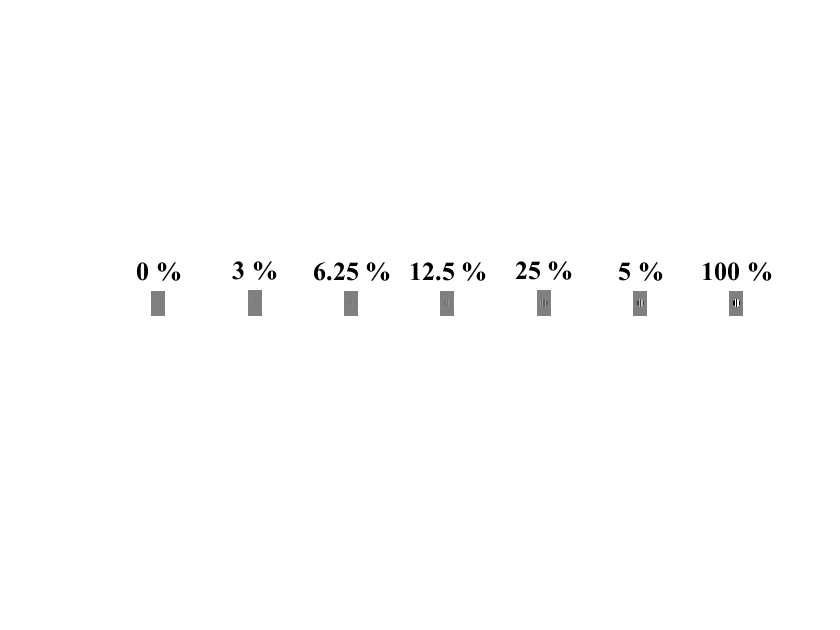


figure
subplot(1,7,1) 
imshow('Con0.png') % con = 0
set(gca, 'FontSize', fntSize, 'FontName', 'Times')
title('0 %', 'Interpreter', 'latex')
%xlabel('0 %', 'Interpreter', 'latex')

subplot(1,7,2)
imshow('ConPt03.png') % con = 0.03
set(gca, 'FontSize', fntSize, 'FontName', 'Times')
title('3 %', 'Interpreter', 'latex')
%xlabel('3 %', 'Interpreter', 'latex')

subplot(1,7,3)
imshow('ConPt0625.png') % con = 0.0625
set(gca, 'FontSize', fntSize, 'FontName', 'Times')
title('6.25 %', 'Interpreter', 'latex')
%xlabel('6.25 %', 'Interpreter', 'latex')

subplot(1,7,4)
imshow('ConPt125.png') % con = 0.125
set(gca, 'FontSize', fntSize, 'FontName', 'Times')
title('12.5 %', 'Interpreter', 'latex')
%xlabel('12.5 %', 'Interpreter', 'latex')

subplot(1,7,5)
imshow('ConPt25.png') % con = 0.25
set(gca, 'FontSize', fntSize, 'FontName', 'Times')
title('25 %', 'Interpreter', 'latex')
%xlabel('25 %', 'Interpreter', 'latex')


subplot(1,7,6)
imshow('ConPt5.png')  % con = 0.5
set(gca, 'FontSize', fntSize, 'FontName', 'Times')
title('5 %', 'Interpreter', 'latex')
%xlabel('5 %', 'Interpreter', 'latex')

subplot(1,7,7)
imshow('Con1.png') % con = 1
set(gca, 'FontSize', fntSize, 'FontName', 'Times')
title('100 %', 'Interpreter', 'latex')
%xlabel('100 %', 'Interpreter', 'latex')

% save plot
print('allStims_fig.png','-dpng')

## ALL INDIVIDUAL ANALYSES BEYOND 'EARLY ANALYSIS' (GROUP & IND VARS)

% CRF BY LOCO
% run & stat SAME PLOT

yMax = 0.1;
yMin = -0.01;

figure 

%titleText = sprintf(': CRF for STAT vs RUN'); % making char variables for sprintf/title later
%suptitle(sprintf('%s', date, subjName, titleText))
formatSpec = '%s %s \n';
titleText = sprintf(formatSpec,subjName,date);
suptitle(titleText)

durat = 1; 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = durat
   % for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthSMALLtrials
             idxCthDthRUNTrials = intersect(idxCthDthTrial,idxRunTrials); % idxLowRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxLowRunTrials(intersect(idxCthDthTrial,idxLowRunTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthRUNTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthRUNTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthRUNTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-r','MarkerSize',3) 
        title(reigons{i})
        
        ylim([yMin yMax]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % ebd i loop
    
end % ebd d loop

hold on 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = durat
    %for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxLowRunTrials); % idxLowRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthSTATtrials = intersect(idxCthDthTrial,idxStatTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSTATtrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSTATtrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSTATtrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3) 
        title(reigons{i})
        
        %ylim([-0.025 0.01]) 
        %xlim([0, 8])
        ylim([yMin yMax]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        hold on 
        
        legend('run','stat')
            
    end % end i loop
    
end % end d loop

    

% CRF BY PUPIL

% small & large SAME PLOT

yMax = 0.1;
yMin = -0.01;

figure 
formatSpec = '%s %s \n';
titleText = sprintf(formatSpec,subjName,date);
suptitle(titleText)

durat = 1; 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = durat
    %for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             % clear idxCthDthRUNtrials
             % idxCthDthRUNtrials = intersect(idxCthDthTrial,idxLowRunTrials); % idxLowRunTrials was made in runSpeed2 script
             
             clear idxCthDthSTATtrials
             idxCthDthLARGEpupTrials = intersect(idxCthDthTrial,idxLargePupilTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthLARGEpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthLARGEpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthLARGEpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-r','MarkerSize',3) 
        title(reigons{i})
        
        %ylim([-0.025 0.01]) 
        %xlim([0, 8])
        ylim([yMin yMax]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        %clear xt
        %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        
        hold on 
        
    end % end d loop

hold on
%legend(durs4Axes)
    
end % end i loop

hold on

% same but 

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = durat
   % for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             clear idxCthDthTrial
             idxCthDthTrial = find(cthDthTrials == 1);
             
             clear idxCthDthSMALLtrials
             idxCthDthSMALLpupTrials = intersect(idxCthDthTrial,idxSmallPupilTrials); % idxLowRunTrials was made in runSpeed2 script
             
             % clear idxCthDthSTATtrials
             % idxCthDthSTATtrials = idxLowRunTrials(intersect(idxCthDthTrial,idxLowRunTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,idxCthDthSMALLpupTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,idxCthDthSMALLpupTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(length(idxCthDthSMALLpupTrials)); % length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        % x_axis = uniqueContrasts;
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-b','MarkerSize',3) 
        title(reigons{i})
        
        ylim([yMin yMax]) 
        %xlim([0, 8])
        %ylim([-0.04 0.08]) 
        xlim([min(x_axis), max(x_axis)])
    
        ylabel('df/f')
        xlabel('contrast')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
       
    end % end d loop

hold on
legend('large','small')
    
end % end i loop